clear variables;
addPath;

%tempo reduction param
para.kF = 20;
para.redL = 5;
para.reduct = false;

%kernel setting
para.kernel = .2;

%ACA param
para.nMi = 15;
para.nMa = 30;
para.ini='r';
para.k=4;
para.nIni=1;

%HACA param
para.haca = false;
if para.haca 
    para2 = para;
    para2.nMi = 3;
    para2.nMa = 8;
    para2.k=4;
    para2.nIni=10;
    paraH = [para para2];
end

%output path
out_path = './output/6/';
mkdir(out_path);

%select cluster num
% sel_num = 2;

## ACA on Select data (mice) and select clusters

all_paths = getAllFile('../feat/20210811/');

nnames = []; % all video names
segResults = {}; % all aca results
Xs = {}; % all data
endss = {}; % all seg point for different video

% multiple
micenames = {'B' , 'DW', 'LKB', 'LW', 'RK', 'SW', 'LKW' , 'MW', 'WT'};
for i=1:size(micenames,2)
    % data process
    micename = micenames{i};
    sel = find(contains(all_paths, ['-',micename,'-']));
    paths=all_paths(sel);
    [X, ends, names] = loadData(paths,para);
    Xs{i} = X;
    endss{i} = ends;
    nnames = [nnames, names];
    % aca
    K = conKnl(conDist(X, X),para.kernel);
    seg = segIniR(K, para);
    if para.haca
        segResult = segHaca(K, paraH, seg);
    else
        segResult = segAca(K, para, seg);
    end
    segResults{i} = segResult;
    disp(i);
end

     1

     2

     3

     4

     5

     6

     7

     8

     9



% save result
X=[];
K=[];
save(strcat(out_path,"tmp.mat"));

## Mice set-Posture distance

nXs = {};
nsegs = {};
for i = 1:size(micenames,2)
    X = Xs{i};
    ends = endss{i};
    if para.haca
        segResult = segResults{i}(2);
    else
        segResult = segResults{i};
    end
    
    [~, ~, ~, labels] = segPart(segResult.s,segResult.G,ends);
    sel = largeDiff(labels, 2, 'treat1diff');
    [nX,nseg,~] = selectCluster(X,segResult.s,segResult.G,sel,ends);
    nXs{i} = nX;
    nsegs{i} = nseg;
end

mice_dist = zeros(size(micenames,2));
for i = 1:size(micenames,2)
    for j = i+1:size(micenames,2)
        mice_dist(i,j) = dtaks2(nXs{i},nsegs{i},nXs{j},nsegs{j},para.kernel);
    end
end
% mice_dist = mice_dist +  triu(mice_dist, 1)';

type_dist = zeros(3);
type_var = zeros(3);
for i=1:3
    for j=i:3
        tmp = mice_dist(i*3-2:i*3,j*3-2:j*3);
        type_dist(i,j) = sum(tmp,'all')/sum(tmp~=0,'all');
        type_var(i,j) = var(tmp(tmp~=0));
    end
end
%%check
% nXs = {};
% nsegs = {};
% for i = 1:8
%     X = Xs{1};
%     segResult = segResults{1};
%     ends = endss{1};
%     [nX,nseg,~] = selectCluster(X,segResult.s,segResult.G,i,ends);
%     nXs{i} = nX;
%     nsegs{i} = nseg;
% end
% 
% mice_dist = zeros(8);
% for i = 1:8
%     for j = i:8
%         mice_dist(i,j) = dtaks2(nXs{i},nsegs{i},nXs{j},nsegs{j});
%     end
% end

## Plot

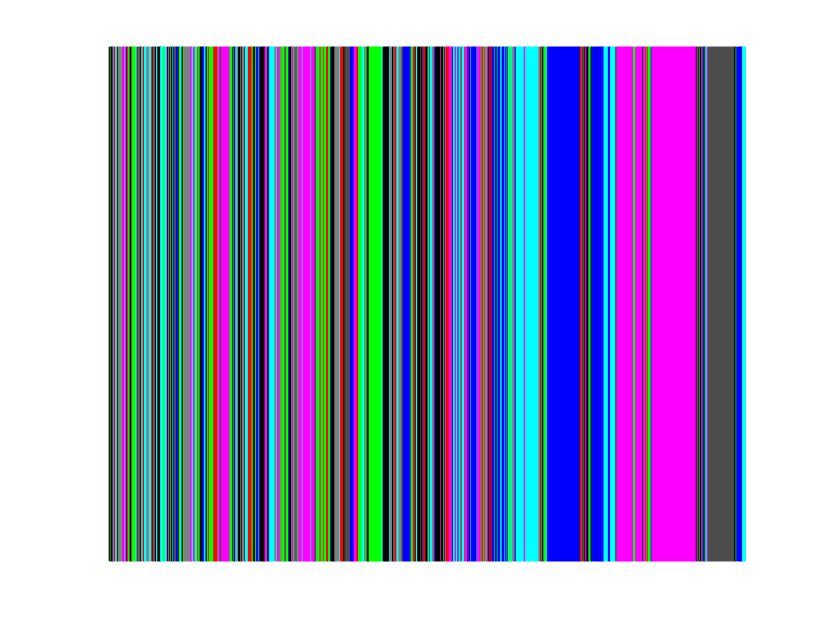

showSegBar(segResults{1}, [1 1 1 1], 0);